# EEG Artifacts

This script investigates how tACS stimulation artifacts affect EEG/LFP analysis and shows results for FASTR, FBAR, and RBAR algorithms.

## Setup Simulation

First define the stimulation and recording parameters.

eeg = artSim;                           % Start with default parameters
eeg.reproducible              = true;    % Fix the random number generator
eeg.duration                  = 2*60;   % 2 min of data
eeg.stimulatorSamplingRate    = 1e3;     % Neuroconn (2 kHz)
eeg.recordingSamplingRate     = 5e3;     % 5kHz
eeg.currentResolution         = 1e-6;    % 1 muA
eeg.tacsAmplitude             = 1e-3;    % 1 mA -> 1 mV artifact
eeg.tacsFrequency             = 10;      % 10 Hz


Define neural noise. No signal for now.

eeg.additive                  = 100e-6;   % Background Noise stdev

Define the common parameters for artifact removal

ar.tacsFrequency             = eeg.tacsFrequency;
ar.recordingSamplingRate     = eeg.recordingSamplingRate;
ar.nrCycles                  = 30;      % 30 cycles per segment
ar.slide                     = false;   % No sliding segment
ar.slack                     = 5e-3;    % 5 ms to realign segments
ar.nrSegsPerWindow           = 10;      % 10 segments to average artifact
ar.pcaNr                     = 2;       % First two PC are removed
ar.pcaVarExplained           = Inf;     % Ignore explained variance, always remove 2.
ar.pcaNrSegsPerWindow        = Inf;     % Use all segments (plus the tACS signal; below) to determine basis set.
ar.referenceSegment          = 1;       % Align to first segment


## Recovering the neural background with FASTR

First, let's investigate the FASTR algorithm (Niazy et al.)

Allocating memory...


ans = 0.0085


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.


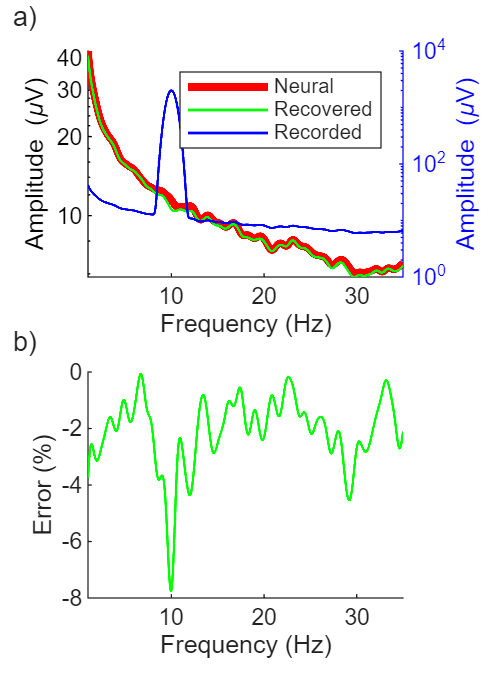

FASTR (r=0.96 rmse = 17/100 muV ae = 2.1%)


eeg.lfpAmplitude = 0; % No neural oscillation
eeg.heartbeatAmplitude = 0; % No physiolgical artifact
    
simPlotEEG(eeg,ar,'FASTR',tag ="3");

Note that the Neural ground truth and the Recovered signals are generally small and show on the left y-axis. The recorded signal, which includes the artifact, is typically orders of magnitude larger - this graph shows it (blue) on the right y-axis. The figure shows that the recovered signal qualitatively matches the neural signal (green vs.red), but a  closer look , expressing errors as a percentage of the neural signal show substantial underestimation of the neural signal not only near the tACS frequency, but across the entire spectrum. 

The low-resolution spectral analysis hides some important detals. Rerun it now with 0.1 Hz frequency resolution:

Allocating memory...


ans = 0.0085


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.


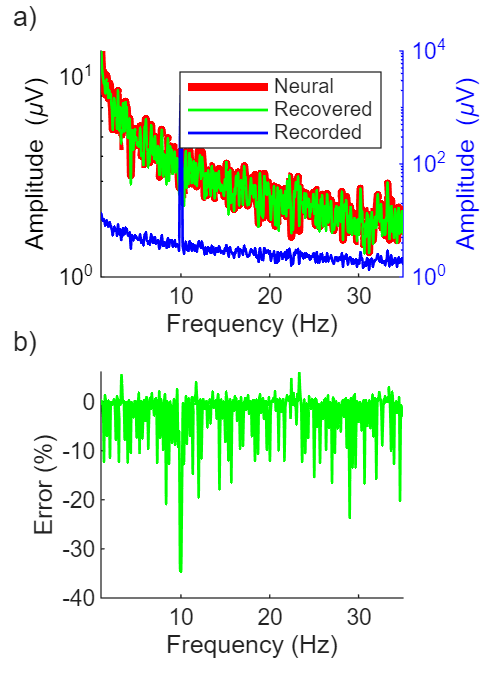

FASTR (r=0.96 rmse = 17/100 muV ae = 2.8%)


simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,tag="4");

This shows the clear comb artifact that repeats at `o.tacsFrequency/o.nrCycles`, here 10/30 = 0.33 Hz.

## Recovering neural signals and background

Next, we add a neural signal in the form of an LFP/EEG signal that peaks at 32 hz, with some spectral spread around that:

eeg.lfpFrequency              = 32;        % Simulated oscillation peak frequency
eeg.lfpAmplitude              = 50e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;        % Oscillation bandwidth.
eeg.heartbeatAmplitude        = 0;        % No physiolgical artifact

[f,axs] = fig('Name','Figure5','paperCols',2,'height',9,'nrRows',2,'nrCols',2,'byColumn',false);


### FASTR


simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=axs([1 2]));

Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 36/100 muV ae = 2.8%)


The bump centered on 32 Hz reflects the neural signal. This has been recovered reasonably well when considering the representation in panel a, but b shows that there are several large errors near the 32 Hz neural signal.

### FBAR

We continue analyzing the same data, but now with a Fourier based algorithm (FBAR)

simPlotEEG(eeg,ar,'FBAR',freqRes =0.1,axs=[gobjects(1) axs(3)]);

FBAR (r=0.99 rmse = 7/100 muV ae = 0.9%)


This method is much better at recovering the original signal- only the forbidden band around the tACS frequency of 10 Hz still has large artifacts.

### RBAR

And a regression based method:

simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1) axs(4)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


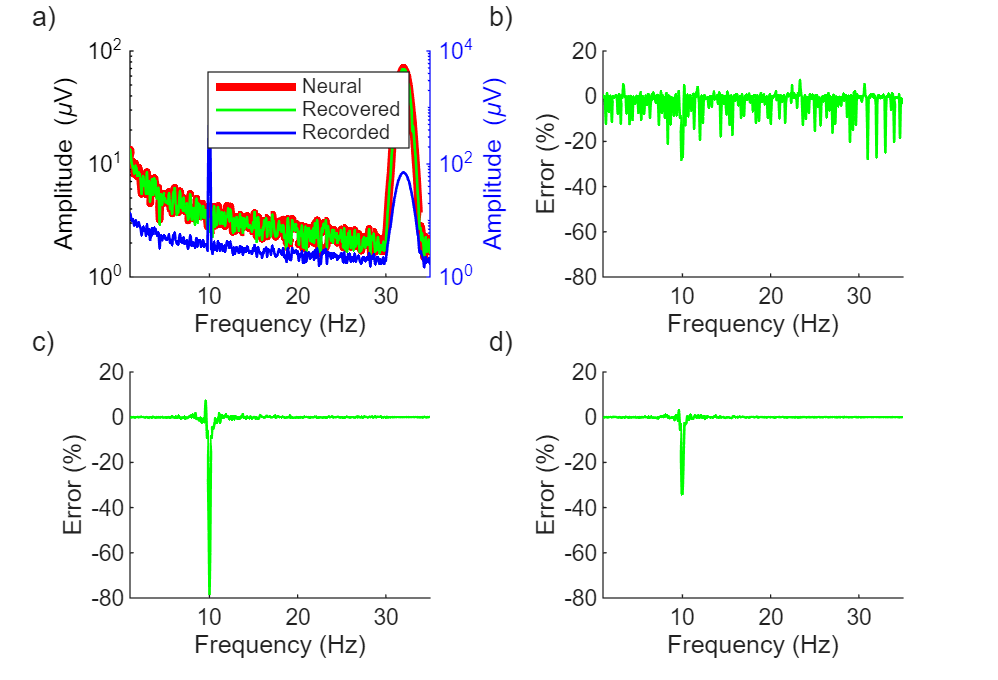

linkaxes(axs(2:4))

The RBAR algorithm performs similarly, with somewhat smaller errors overall.

### Signal frequency dependence

The above analysis focuses only on a single intrinsic oscillation, here I do repeat this for a range of frequencies to show that the relative performance of the methods is approximately the same no matter what the neural signal is. 

eeg.lfpAmplitude              = 50e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;        % Oscillation bandwidth.
eeg.heartbeatAmplitude        = 0;        % No physiolgical artifact

methods = ["FASTR","FBAR", "RBAR"];
signalFreqs = 2.^(0:5);  % Test these frequencies
nrFreqs = numel(signalFreqs);
nrMethods = numel(methods);
forbiddenBand = nan(nrFreqs,nrMethods);
forbidden = nan(nrFreqs,nrMethods);
mre = nan(nrFreqs,nrMethods);
for m=1:nrMethods
for  f = 1:nrFreqs
   eeg.lfpFrequency = signalFreqs(f);
   results = simPlotEEG(eeg,ar,methods(m),freqRes =0.1,axs=[nan nan],errorThreshold=1,fillHz=0.1);  % Same analysis as above, without figure
   forbiddenBand(f,m) = results.forbiddenBand; 
   forbidden(f,m) = results.forbidden;
   mre(f,m) = results.meanPctError;
end
end

Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 33/100 muV ae = 2.7%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 34/100 muV ae = 2.7%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 35/100 muV ae = 2.6%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 35/100 muV ae = 2.7%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 36/100 muV ae = 2.9%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 36/100 muV ae = 2.8%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.8%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.8%)
FBAR (r=0.99 rmse = 8/100 muV ae = 0.8%)
FBAR (r=0.99 rmse = 11/100 muV ae = 1.1%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.8%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.9%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


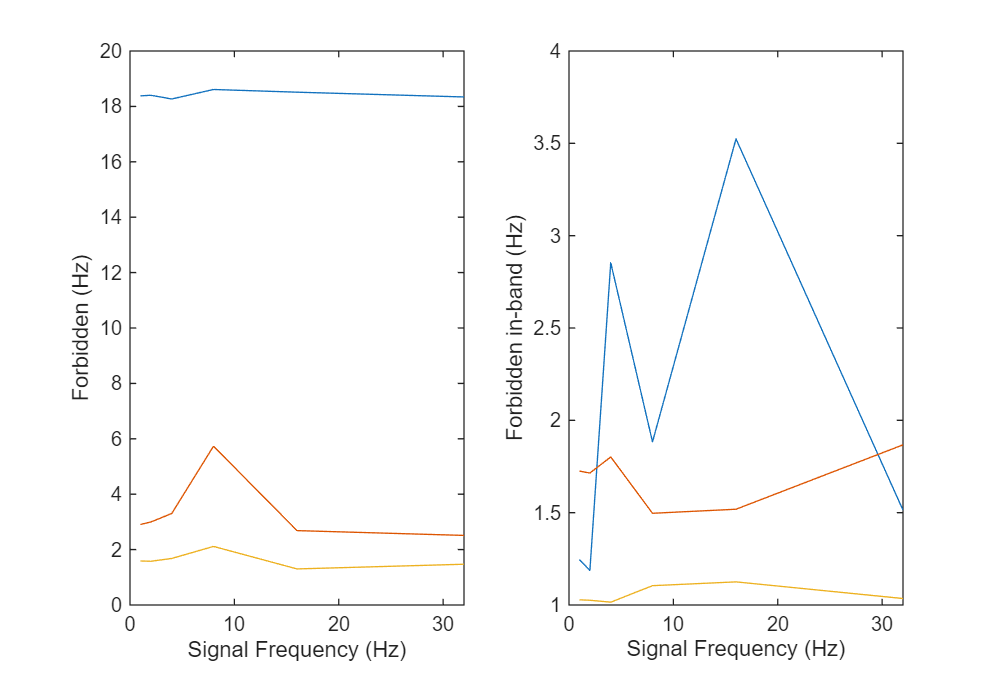

clf;
subplot(1,2,1)
plot(signalFreqs,forbidden)
xlabel 'Signal Frequency (Hz)'
ylabel 'Forbidden (Hz)'

subplot(1,2,2)
plot(signalFreqs,forbiddenBand)
xlabel 'Signal Frequency (Hz)'
ylabel 'Forbidden in-band (Hz)'


mean(forbidden)

ans =    18.4191    3.3566    1.6230


std(forbidden)

ans =     0.1237    1.1956    0.2735


mean(mre)

ans =     2.7286    0.8582    0.4108


### Segment length dependence

RBAR does a good job removing artifacts, but it still has a ~2 Hz forbidden zone in the simulations above. Because the residual artifacts are essentially due to the windowing/segmenting, this can be improved by increasing segment size. Note, however, that this comes at a cost of a reduced ability to follow changes in the artifacts over time (i.e. dealing with non-stationary artifacts). The simulation below has a stationary artifact hence it ignores this tradeoff. 

eeg.lfpAmplitude              = 50e-6;    % Oscillation peak amplitude
eeg.lfpPeakWidth              = 1;        % Oscillation bandwidth.
eeg.heartbeatAmplitude        = 0;        % No physiolgical artifact
eeg.lfpFrequency              = 20;

nrCyclesPerSegment = [10 20 40 80 160];  
nrSims = numel(nrCyclesPerSegment);
methods = ["FASTR","FBAR", "RBAR"];
nrMethods = numel(methods);
forbidden = nan(nrSims,nrMethods);
mre = nan(nrSims,nrMethods);
for m=1:nrMethods
for  s = 1:nrSims
   ar.nrCycles= nrCyclesPerSegment(s);
   results = simPlotEEG(eeg,ar,methods(m),freqRes =0.1,axs=[nan nan],errorThreshold=1,fillHz=0.1);  
   forbidden(s,m) = results.forbidden;
   mre(s,m) = results.meanPctError;
end
end

Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 1 sec.
FASTR (r=0.97 rmse = 37/100 muV ae = 3.8%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% 75% FASTR Finished in 0 min 0 sec.
FASTR (r=0.95 rmse = 46/100 muV ae = 3.3%)
Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.91 rmse = 56/100 muV ae = 3.9%)


Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
...25% ...50% ...75% ..100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.89 rmse = 63/100 muV ae = 5.2%)
Non-integer number of segments (7.50).


Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
.25% .50% .75% .100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.63 rmse = 114/100 muV ae = 41.9%)
FBAR (r=0.99 rmse = 10/100 muV ae = 2.0%)
FBAR (r=0.99 rmse = 8/100 muV ae = 1.1%)
FBAR (r=0.99 rmse = 7/100 muV ae = 0.6%)
FBAR (r=0.99 rmse = 5/100 muV ae = 0.3%)
Non-integer number of segments (7.50).
FBAR (r=0.99 rmse = 5/100 muV ae = 0.2%)
RBAR (r=1.00 rmse = 3/100 muV ae = 0.9%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.7%)
RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)
Non-integer number of segments (7.50).
RBAR (r=1.00 rmse = 1/100 muV ae = 0.1%)


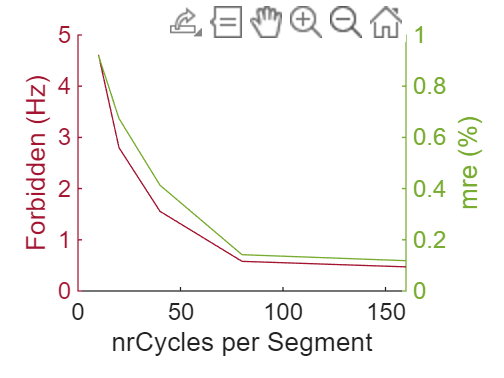

[f,axs] = fig('Name','Figure7','paperCols',1,'height',5,'nrRows',1,'nrCols',1);
yyaxis left
plot(nrCyclesPerSegment',forbidden(:,3))
xlabel 'nrCycles per Segment'
ylabel 'Forbidden (Hz)'
yyaxis right
plot(nrCyclesPerSegment',mre(:,3))
ylabel 'mre (%)'

The figure confirms that the forbidden zone (and the mre) decrease rapidly with increasing segment sizes (here expressed in the number of tACS cycles per segment).

## Recovering Neural Signal in the Presence of Impedance Artifacts

Physiological artifacts such as heartbeats, sweating, or breathing change impedance and interact multiplicatively with the signal. FASTR has a hard time recovering any underlying signals.

Keeping the neural signals from above, but adding an artifact that rhytmically (`o.heartbeatFrequency`) changes the impedance sinusoidally, or abruptly for short periods of time (`o.heartbeatDuration`)

eeg.lfpAmplitude = 50e-6;
eeg.lfpFrequency = 23;
eeg.heartbeatFrequency = 0.43;
eeg.heartbeatAmplitude = 0.05;  % The artifact will change the impedance by 5%.
ar.nrCycles =30;

[f,axs] = fig('Name','Figure6','paperCols',1.5,'height',9,'nrRows',2,'nrCols',2);

First we simulate a sinusoidal modulation of the impedance (maybe a reasonable approximation for respiration not so much for a heartbeat):

eeg.heartbeatDuration = 0; % Purely sinusoidal, multiplicative artifact
simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1) axs(1)]);

Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.94 rmse = 48/100 muV ae = 13.9%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1) axs(2)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


Next we simulate a impedance modulation that is more abrupt (akin to the ballistic artifacts expected from a heartbeat). 

eeg.heartbeatDuration = 0.125; % 125 ms pulses
eeg.heartbeatFrequency = 0.9;
simPlotEEG(eeg,ar,'FASTR',freqRes =0.1,axs=[gobjects(1) axs(3)]);

Allocating memory...


ans = 0.1069


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 1 sec.
FASTR (r=0.96 rmse = 37/100 muV ae = 9.3%)


simPlotEEG(eeg,ar,'RBAR',freqRes =0.1,axs=[gobjects(1) axs(4)]);

RBAR (r=1.00 rmse = 2/100 muV ae = 0.4%)


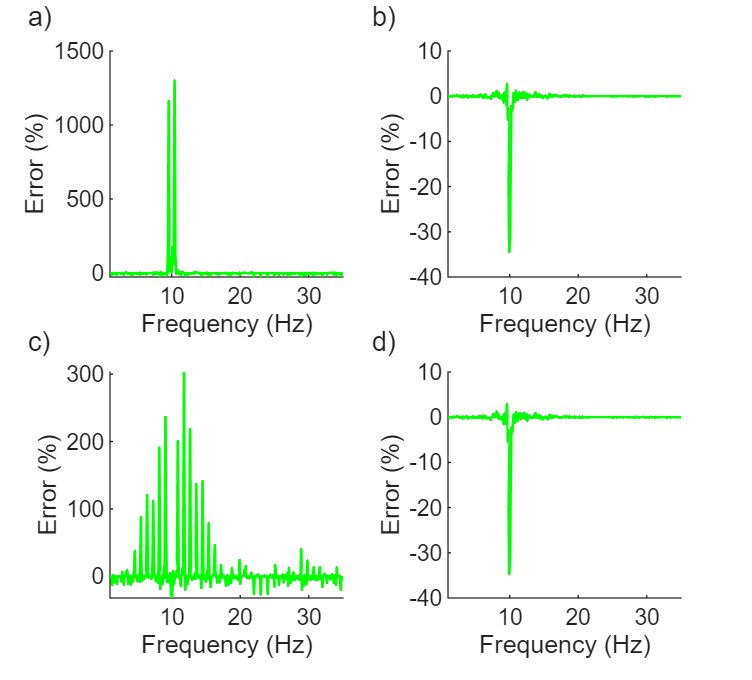

linkaxes(axs([2 4]))

Clearly FASTR (a,c) does not recover the neural signal of either sinusoidal (a) or pulsed (c) impedance artifacts; the multiplicative interactions between physiological artifacts and the true neural signal results in spurious signals across the entire spectrum.  Noury et al explain why this should happen and why there are two prominent peaks in a).  RBAR gets rid of most artifacts and only has a small forbidden zone near the tACS frequency. FBAR (not shown) has the same kind of issues as FASTR.